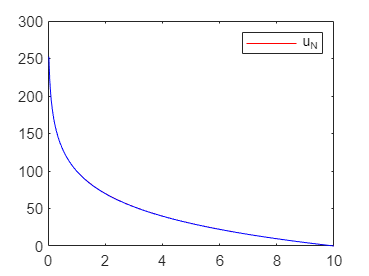

% 1.2 a)
read_1D_mesh;
read_1D_input;
psi = polyLagrange(1); %1 dimensional case
[ke,fe] = jelement1D(psi); %create element functions
K = zeros(nElems+1); %initialize
F = zeros([nElems+1, 1]);

for i=1:nElems
    nodelist = MESH.ConnectivityList(i,:); %make our nodelist
    he = MESH.Points(nodelist(2))-MESH.Points(nodelist(1)); %lengths of each element
    ki = 2/he*KofX(i).*(ke.k)+he/2*BofX(i).*(ke.b); %stiffness matrix of i-th element
    fi = he/2*FofX(i).*fe; %load vector of i-th element
    [K,F] = jassembly1D(M,K,F,mi,ki,fi,nodelist); %assembly
end

[K,F] = jenforceBCs(boundaryNodes, boundaryValues, K, F, KofX); %enforce BCs
U = K\F; %solve
fem1Dplot(MESH, U, psi)
hold off

% 1.2 b)
exact = 100/log(10)*log(10/3.25);
%Determine degree of shape function
    p = length(psi)-1;
    %uPlot = zeros(40,1);
    %Divide the master element into enough points to get smooth plot
    xi = linspace(-1,1,40)';
    %Evaluate the shape functions at the set of plotting pts.
    ShapeFunctionValues = zeros(40,p+1);
    for i=1:p+1
        ShapeFunctionValues(:,i) = polyval(psi(i).fun,xi);
    end
    %loop over elements
    for j=1:nElems
        %retrieve global node #s
        firstNode = MESH.ConnectivityList(j,1);
        lastNode = MESH.ConnectivityList(j,2);
        %compute FEM solution at the plotting points
        uPlot(:,j) = ShapeFunctionValues*U(firstNode:lastNode);
        %compute the points oveer element in x-coords
        %xPlot = linspace(MESH.Points(firstNode),MESH.Points(lastNode),40);

        %plot(xPlot,uPlot, 'r'); hold on;
        
    end
 x = floor(2.25/(9/nElems))+1;
 y = 2.25 - (9/nElems);
 k = 0;
 while y < 2.25
     y = y + (9/nElems)/40;
     k = k + 1;
 end
u_r = uPlot(1, x);
abs(exact - u_r)

ans = 0.0562

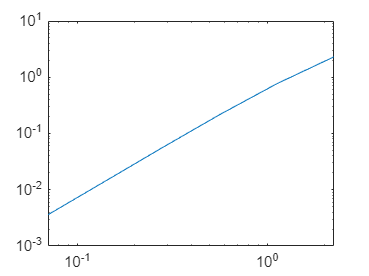

ans =     1.0679   -0.2272


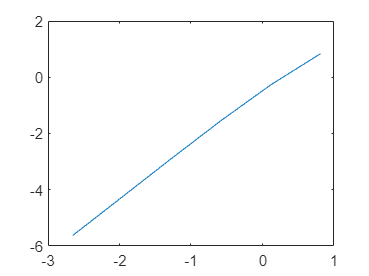

ans =     1.8809   -0.5524


% 1.2 c)
error = log([2.3102 0.7667 0.2162 0.0562 0.0142 0.0036])';
h = log([2.25 1.125 0.5625 0.2812 0.1406 0.0703])';
plot(h, error,'o')
pm = polyfit(h,error,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(pm,x1);
plot(x1,y1)
xlabel('log h')
ylabel('log(error)')
hold off

% 1.2 d)
read_1D_mesh;
read_1D_input;
psi = polyLagrange(1); %1 dimensional case
[ke,fe] = jelement1D(psi); %create element functions
K = zeros(nElems+1); %initialize
F = zeros([nElems+1, 1]);

for i=1:nElems
    nodelist = MESH.ConnectivityList(i,:); %make our nodelist
    he = MESH.Points(nodelist(2))-MESH.Points(nodelist(1)); %lengths of each element
    h(i) = MESH.Points(nodelist(2))-MESH.Points(nodelist(1));
    ki = 2/he*KofX(i).*(ke.k)+he/2*BofX(i).*(ke.b); %stiffness matrix of i-th element
    fi = he/2*FofX(i).*fe; %load vector of i-th element
    [K,F] = jassembly1D(K,F,ki,fi,nodelist); %assembly
end

[K,F] = jenforceBCs(boundaryNodes, boundaryValues, K, F, KofX); %enforce BCs
U = K\F; %solve
fem1Dplot(MESH, U, psi)
hold off


exact = 100/log(10)*log(10/3.25);
%Determine degree of shape function
    p = length(psi)-1;
    %uPlot = zeros(40,1);
    %Divide the master element into enough points to get smooth plot
    xi = linspace(-1,1,40)';
    %Evaluate the shape functions at the set of plotting pts.
    ShapeFunctionValues = zeros(40,p+1);
    for i=1:p+1
        ShapeFunctionValues(:,i) = polyval(psi(i).fun,xi);
    end
    %loop over elements
    for j=1:nElems
        %retrieve global node #s
        firstNode = MESH.ConnectivityList(j,1);
        lastNode = MESH.ConnectivityList(j,2);
        %compute FEM solution at the plotting points
        uPlot(:,j) = ShapeFunctionValues*U(firstNode:lastNode);
        %compute the points oveer element in x-coords
        %xPlot = linspace(MESH.Points(firstNode),MESH.Points(lastNode),40);

        %plot(xPlot,uPlot, 'r'); hold on;
        
    end
%  x = floor(2.25/(9/nElems))+1;
%  y = 2.25 - (9/nElems);
%  k = 0;
%  while y < 2.25
%      y = y + (9/nElems)/40;
%      k = k + 1;
%  end
u_r = uPlot(1, 6); %these indices are for the unstructured mesh

Index in position 2 exceeds array bounds. Index must not exceed 4.

abs(exact - u_r)

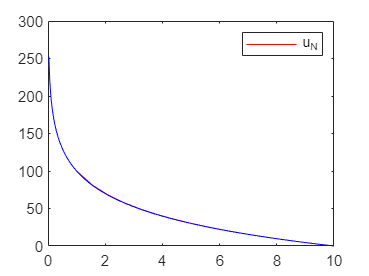

% 1.2 e)
read_1D_mesh;
read_1D_input;
psi = polyLagrange(1); %1 dimensional case
[ke,fe] = jelement1D(psi); %create element functions
K = zeros(nElems+1); %initialize
F = zeros([nElems+1, 1]);

for i=1:nElems
    nodelist = MESH.ConnectivityList(i,:); %make our nodelist
    he = MESH.Points(nodelist(2))-MESH.Points(nodelist(1)); %lengths of each element
    h(i) = MESH.Points(nodelist(2))-MESH.Points(nodelist(1));
    ki = 2/he*KofX(i).*(ke.k)+he/2*BofX(i).*(ke.b); %stiffness matrix of i-th element
    fi = he/2*FofX(i).*fe; %load vector of i-th element
    [K,F] = jassembly1D(K,F,ki,fi,nodelist); %assembly
end

[K,F] = jenforceBCs(boundaryNodes, boundaryValues, K, F, KofX); %enforce BCs
U = K\F; %solve
fem1Dplot(MESH, U, psi)
hold off


exact = 170/log(10);
%Determine degree of shape function
    p = length(psi)-1;
    %uPlot = zeros(40,1);
    %Divide the master element into enough points to get smooth plot
    xi = linspace(-1,1,40)';
    %Evaluate the shape functions at the set of plotting pts.
    ShapeFunctionValues = zeros(40,p+1);
    for i=1:p+1
        ShapeFunctionValues(:,i) = polyval(psi(i).fun,xi);
    end
    %loop over elements
    for j=1:nElems
        %retrieve global node #s
        firstNode = MESH.ConnectivityList(j,1);
        lastNode = MESH.ConnectivityList(j,2);
        %compute FEM solution at the plotting points
        uPlot(:,j) = ShapeFunctionValues*U(firstNode:lastNode);
        %compute the points oveer element in x-coords
        %xPlot = linspace(MESH.Points(firstNode),MESH.Points(lastNode),40);

        %plot(xPlot,uPlot, 'r'); hold on;
        
    end
%  x = floor(2.25/(9/nElems))+1;
%  y = 2.25 - (9/nElems);
%  k = 0;
%  while y < 2.25
%      y = y + (9/nElems)/40;
%      k = k + 1;
%  end

u_1 = 1*1.7*((uPlot(1, 1)-uPlot(end, 1))/he);
u_10 = 1*1.7*10*((uPlot(1,end)-uPlot(end,end))/he);
abs(exact - u_1)/exact*100

ans = 21.5281

ans = 3.4517

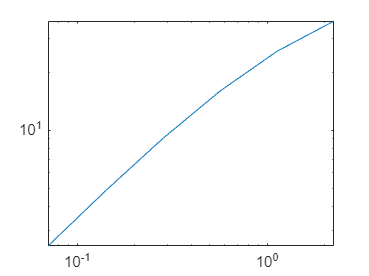

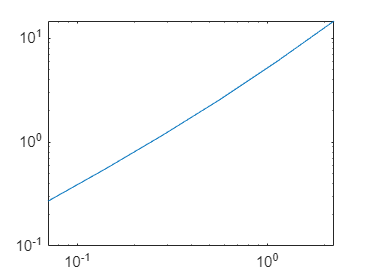

ans =     0.7849    3.1081


ans =     1.1489    1.6659


abs(exact - u_10)/exact*100

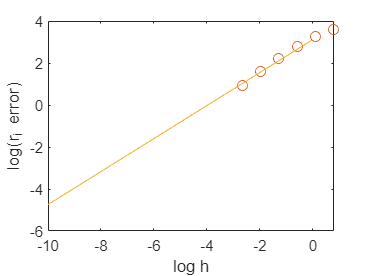

% 1.2 f)
errori = log([36.9 25.65 15.9 9.01 4.82 2.50])';
erroro = log([14.59 5.94 2.55 1.16 0.55 0.27])';
h = log([2.25 1.125 0.5625 0.2812 0.1406 0.0703])';
plot(h, errori,'o')
p = polyfit(h,errori,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(p,x1);
plot(x1,y1)
xlabel('log h')
ylabel('log(r_{i} error)')
hold off

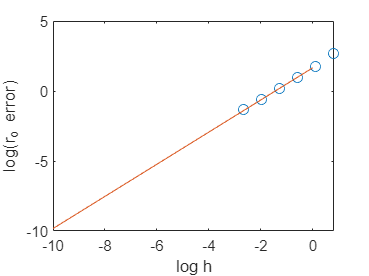


plot(h, erroro,'o')
pm = polyfit(h,erroro,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(pm,x1);
plot(x1,y1)
xlabel('log h')
ylabel('log(r_{o} error)')
hold off

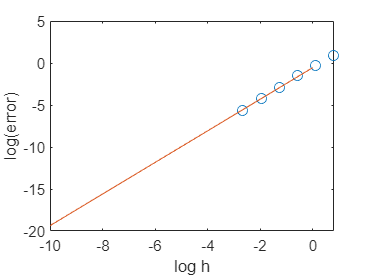

% 2.2 a)

read_2D_mesh;                %read mesh
read_2D_input;               %read input

degree = 1;                  %input degree of shape functions
psi = bipolyLagrange(degree);  %obtain shape functions

K = zeros(nNodes);
F = zeros(nNodes,1);

for n=1:nElems
    nodelist = MESH.ConnectivityList(n,:);
    xcoords = MESH.Points(nodelist,1);
    ycoords = MESH.Points(nodelist,2);
    [Ke,Fe] = element2D(xcoords, ycoords, KofXY(n,1),BofXY(n,1),FofXY(n,1));   
    [K,F] = assemble2D(K,F,Ke,Fe,nodelist);
end

[K,F] = BCType1(boundaryNodes, boundaryValues, K, F);
U = K\F;

trimesh(MESH.ConnectivityList,MESH.Points(:,1),MESH.Points(:,2),U)
colormap default;
hold off;
% hold on
% x = linspace(0,1,100);
% y = x';
% z = (cosh(10*x)+cosh(10*y))/(2*cosh(10));
% surf(x,y,z)

[errorL2,errorMax] = error2D(MESH, U, nElems);

f = @() proj2_2;
t= timeit(f)

% 2.2 c)
h = log([0.1250 0.0625 0.0313])';
L2 = log([0.0212 0.0056 0.0014])';
Linf = log([0.0974 0.0342 0.0102])';
plot(h,L2,'o')
p = polyfit(h,L2,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(p,x1);
plot(x1,y1)
xlabel('log area')
ylabel('log(L^{2} error)')
hold off

plot(h,Linf,'o')
pm = polyfit(h,Linf,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(pm,x1);
plot(x1,y1)
xlabel('log area')
ylabel('log(L^{max} error)')
hold off